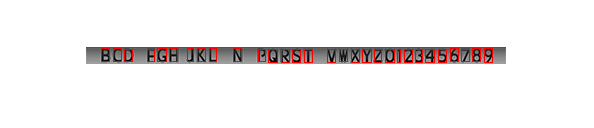

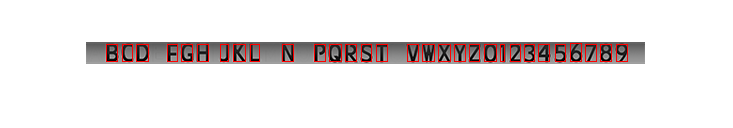

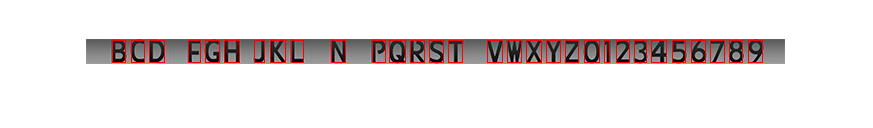

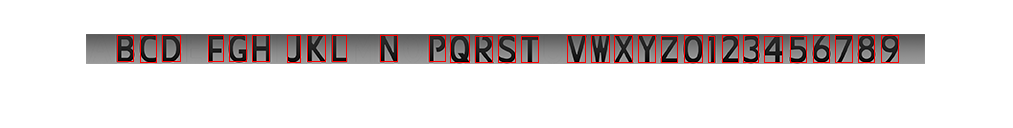

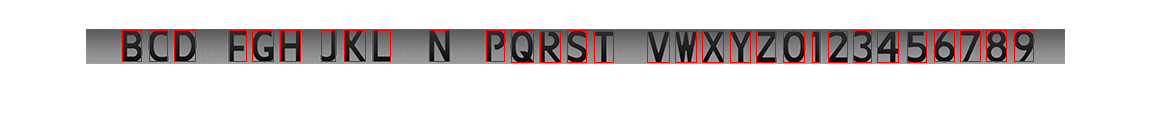

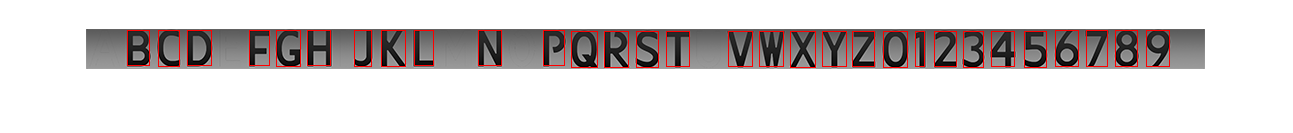

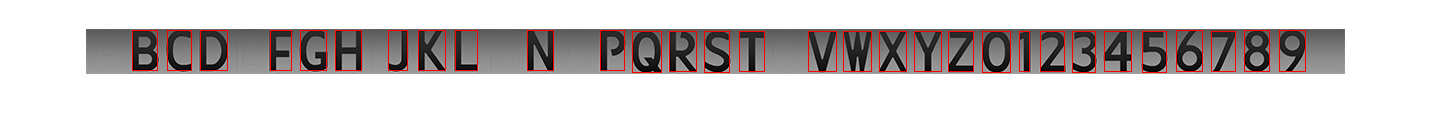

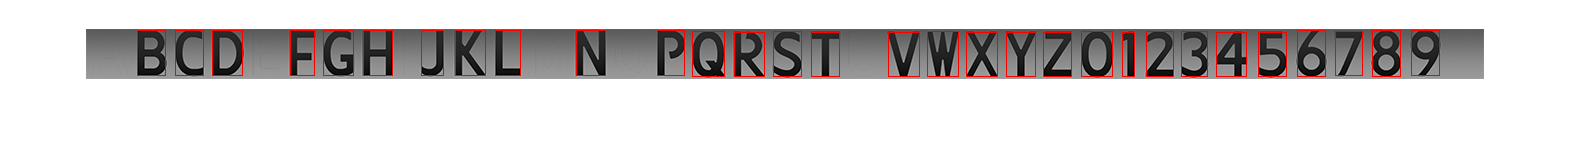

clear
lvl = [15 20 25 30 35 40 45 50];

temps = cell(1,length(lvl));
for i = 1:1:length(lvl)
    filename = sprintf(['data/letters_dutch_%d_shadow.png'],lvl(i));
    font = imread(filename);
    BBs = getCharBBs(font);
    BBs = filterBBs(BBs);
    figure()
    imshow(overlayBB(font, BBs))
    cuts = cutOuts(font, BBs);
    temps{i} = zeros(32,length(cuts));
    for j = 1:1:length(cuts)
        temps{i}(:,j) = getDirSingle(cuts{j}, 16);
    end
end


trans = ['B';'C';'D';'F';'G';'H';'J';'K';'L';'N';'P';'Q';'R';'S';'T';'V';'W';'X';'Y';'Z';'0';'1';'2';'3';'4';'5';'6';'7';'8';'9'];
template = [];
transform = [];
for i = 1:1:length(lvl)
    template = [template,temps{i}];
    transform = [transform; trans];
end
